Calculation of population of NV- center under zero-field (B = 0), using equation (11) from http://arxiv.org/abs/2104.00744

clear 
clc
close all
% syms n0(t) [1 7]    % [n0_1(t) n0_2(t) ... n0_7(t)]
% syms n01(t) n02(t) n03(t) n04(t) n05(t) n06(t) n07(t)

K0 = zeros(7,7);

beta = 0.03;
k0_r = 63;
k0_47 = 13;
k0_57 = 80;
k0_71 = 3.5;
k0_72 = 2.2;
K0(1,4) = beta*k0_r;
K0(2,5) = beta*k0_r;
K0(3,6) = beta*k0_r;
K0(4,1) = k0_r;
K0(5,2) = k0_r;
K0(6,3) = k0_r;
K0(4,7) = k0_47;
K0(5,7) = k0_57;
K0(6,7) = k0_57;
K0(7,1) = k0_71;
K0(7,2) = k0_72;
K0(7,3) = k0_72;

% ode1 = diff(n0(1)) == NV_sum(1, K0, n0);
% ode2 = diff(n0(2)) == NV_sum(2, K0, n0);
% ode3 = diff(n0(3)) == NV_sum(3, K0, n0);
% ode4 = diff(n0(4)) == NV_sum(4, K0, n0);
% ode5 = diff(n0(5)) == NV_sum(5, K0, n0);
% ode6 = diff(n0(6)) == NV_sum(6, K0, n0);
% ode7 = diff(n0(7)) == NV_sum(7, K0, n0);

% ode1 = diff(n01) == K0(3,1)*n03 + K0(7,1)*n07 - K0(1,4)*n01
% ode2 = diff(n02) == K0(5,2)*n05 + K0(7,2)*n07 - K0(2,5)*n02
% ode3 = diff(n03) == K0(6,3)*n06 + K0(7,3)*n07 - K0(3,6)*n03
% ode4 = diff(n04) == K0(1,4)*n01 - (K0(4,1) + K0(4,7))*n04
% ode5 = diff(n05) == K0(2,5)*n02 - (K0(5,2) + K0(5,7))*n05
% ode6 = diff(n06) == K0(3,6)*n03 - (K0(6,3) + K0(6,7))*n06
% ode7 = diff(n07) == K0(4,7)*n04 + K0(5,7)*n05 + K0(6,7)*n06 - (K0(7,1) + K0(7,2) + K0(7,3))*n07

ode1 = @(t, n) K0(3,1)*n(3) + K0(7,1)*n(7) - K0(1,4)*n(1);
ode2 = @(t, n) K0(5,2)*n(5) + K0(7,2)*n(7) - K0(2,5)*n(2);
ode3 = @(t, n) K0(6,3)*n(6) + K0(7,3)*n(7) - K0(3,6)*n(3);
ode4 = @(t, n) K0(1,4)*n(1) - (K0(4,1) + K0(4,7))*n(4);
ode5 = @(t, n) K0(2,5)*n(2) - (K0(5,2) + K0(5,7))*n(5);
ode6 = @(t, n) K0(3,6)*n(3) - (K0(6,3) + K0(6,7))*n(6);
ode7 = @(t, n) K0(4,7)*n(4) + K0(5,7)*n(5) + K0(6,7)*n(6) - (K0(7,1) + K0(7,2) + K0(7,3))*n(7);
odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

## Solving the system numerically

% M = matlabFunction(odes, 'vars', {'t', 'n0'})
% sol = ode45(M,[0, 20], [1/3, 1/3, 1/3, 0,0,0,0]);
cond1 = 1/3;
cond2 = 1/3;
cond3 = 1/3;
cond4 = 0;
cond5 = 0;
cond6 = 0;
cond7 = 0;
conds = [cond1; cond2; cond3; cond4; cond5; cond6; cond7];

[t, n_res] = ode45(odes, [0:5e-3:20000e-3], conds);

### Plotting

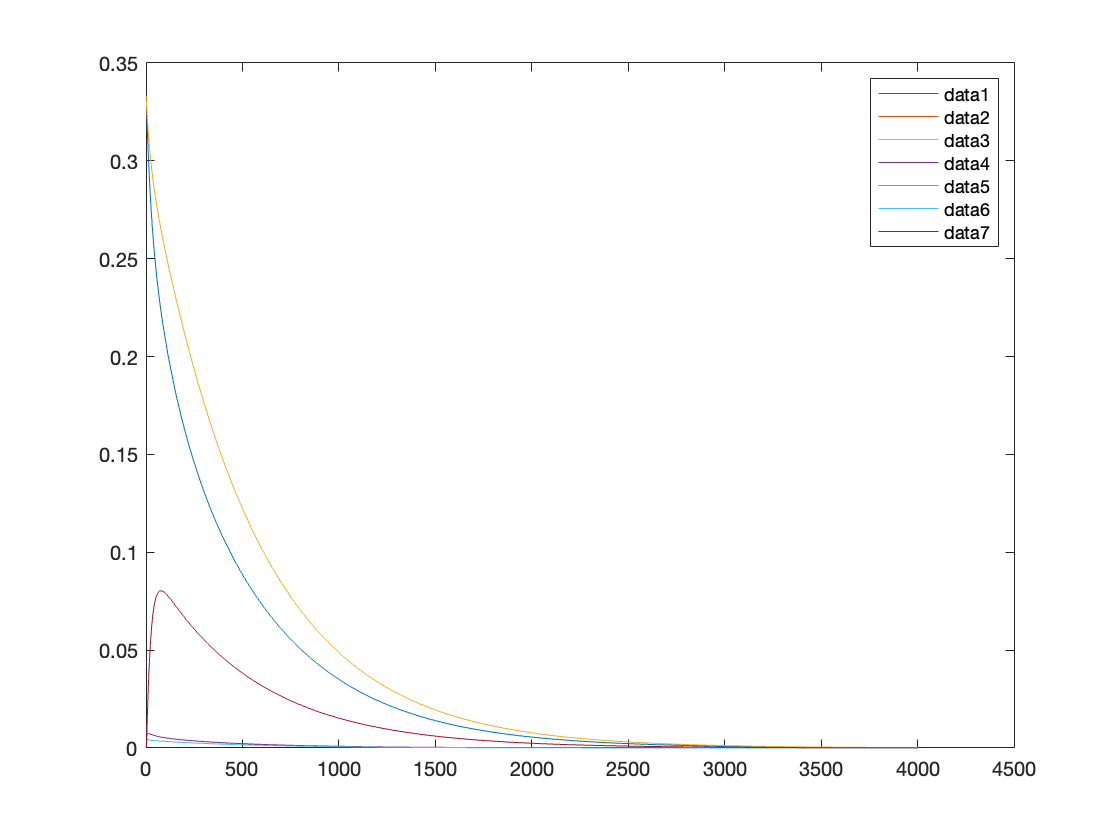

% figure; plot(sol.x,sol.y)
% legend
plot(n_res)
legend

## Solving the system analytically (ignore this part)

### Initial conditions

cond1 = n01(0) == 1/3;
cond2 = n02(0) == 1/3;
cond3 = n03(0) == 1/3;
cond4 = n04(0) == 0;
cond5 = n05(0) == 0;
cond6 = n06(0) == 0;
cond7 = n07(0) == 0;
conds = [cond1; cond2; cond3; cond4; cond5; cond6; cond7];

sol = dsolve(odes, conds)

sol = struct with fields:
    n02: [1×1 sym]
    n01: [1×1 sym]
    n03: [1×1 sym]
    n04: [1×1 sym]
    n05: [1×1 sym]
    n06: [1×1 sym]
    n07: [1×1 sym]


% disp(sol.n01)

fplot(sol.n01)  % was able to obtain analytical solutions, but plotting takes too long (5+ minutes)

function sum = NV_sum(i, K0, n0)
%     syms sum(t);
    sum = 0;
    for j = 1 : 7
        sum = sum + (K0(j,i) * n0(j) - K0(i,j) * n0(i));
    end
end
